# Kalman filtering example

## Estimate the level of water in a tank

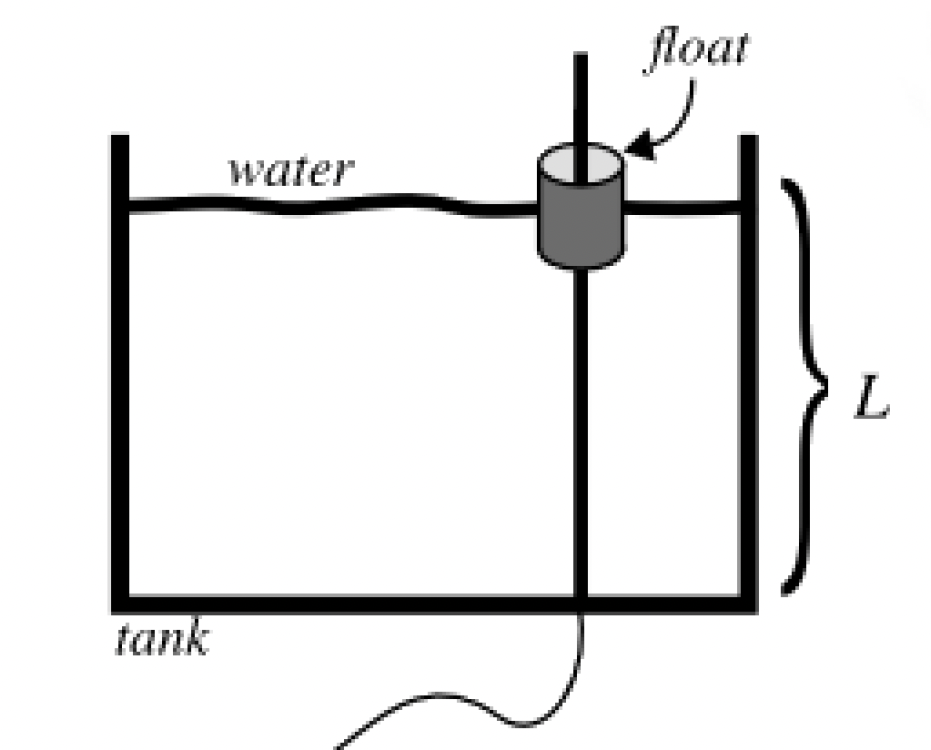

clearvars
close all

## First case: constant level

Import the data

data_tab = importdata('Constant_level.xlsx'); % Load data from table
y_true = data_tab.data(:,1); % Get the true value of the output
x_true = y_true; % The state coincides with the output (see later)
y_meas = data_tab.data(:,2); % Get the measurements
u      = zeros(length(y_meas),1); % No input affects the evolution of the level of water

Compare the actual state **(generally not available in practice)** and the measurements

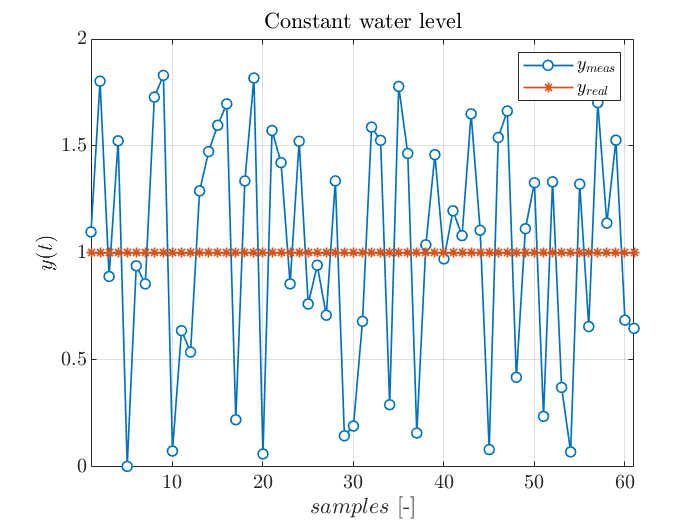

% Superimpose the plots of the true state and the measured output
figure(1); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(y_meas, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$y_{meas}$');
plot(y_true, '-*', 'Linewidth', 1, 'DisplayName', '$y_{real}$');
legend('Interpreter', 'latex');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$y(t)$', 'Interpreter', 'latex');
title('Constant water level', 'Interpreter', 'latex');
xlim([1, length(y_true)]); clf;

### Static model

Define the model $L\left(t+1\right)=L\left(t\right)$ (constant Level). We can define $L\left(t\right)=x\left(t\right)$:


$$\begin{array}{l}
x\left(t+1\right)=x\left(t\right)+v_1 \left(t\right)\\
y\left(t\right)=x\left(t\right)+v_2 \left(t\right)
\end{array}$$


F = 1; % The value of the state at t+1 is equal to that of the state at t
G = 0; % No exogenous input affects the level of water
H = 1; % The state is fully measured
V1 = 1e-4; % We trust the model
V2 = 0.1; % We have less trust on the measurements

Note that, V2 **does not correspond** to the **true variance** of the measurement noise (equal to 2). Indeed, we assume we do not know it exactly.

Initialize the predicted state and covariance matrix. We thus firstly perform the correction** step** and, then, the prediction** step **(by initializing the corrected state and covariance matrix the order of the steps can be straightfowardly reversed).

x_predInit = 0; % Initial predicted state
P_predInit = 1e3; % Initial predicted state covariance

The chosen initialization of the corrected covariance entails that we do not trust the initial predicted state

Initialization of all corrected and predicted states, along with the Kalman Gain

x_corr = zeros(length(y_meas), 1);
x_pred = zeros(length(y_meas)+1, 1);
P_corr = zeros(length(y_meas), 1);
P_pred = zeros(length(y_meas)+1, 1);
x_pred(1) = x_predInit;
P_pred(1) = P_predInit;
K = zeros(length(y_meas), 1);

#### Kalman filtering steps

for t = 1:length(y_meas)
   % Correction step
   [K(t), x_corr(t), P_corr(t)] = kf_correction(y_meas(t), H, V2, x_pred(t), P_pred(t)); 
   % Prediction step
   [x_pred(t+1), P_pred(t+1)] = kf_prediction(u(t), F, G, V1, x_corr(t), P_corr(t));
end

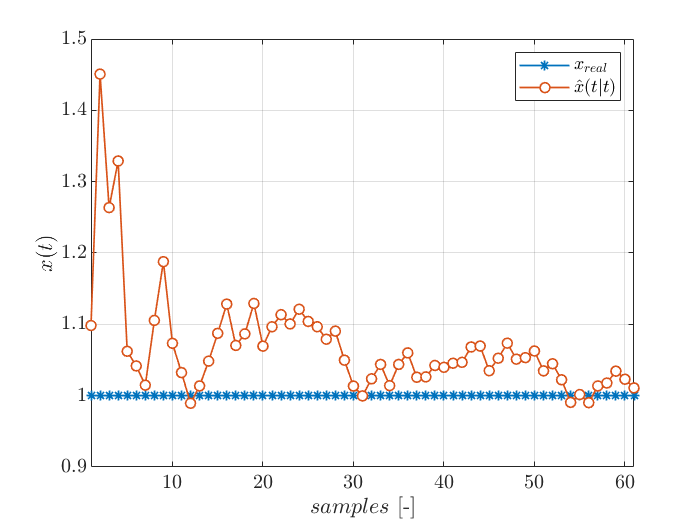

% Superimpose the plots of the true state and the corrected state
figure(2); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(x_true, '-*', 'Linewidth', 1, 'DisplayName', '$x_{real}$');
plot(x_corr, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
xlim([1, length(x_true)]); clf;

As it can be seen, the estimate converges to the true value of the state.

Obtain the asymptotic Kalman filter and check the convergence to it. We will use MATLAB's built-in function `kalman`. It has the following inputs and outputs:

`[KF_model, `$\bar{K}$`, `$\bar{P}$`] = kalman(system_model, V1, V2, V12)`

Being `system_model` thhe system model expressed as follows:


$$\begin{array}{l}
x\left(t+1\right)=\textrm{Fx}\left(t\right)+G_u u\left(t\right)+G_{v_1 } v_1 \left(t\right)\\
y\left(t\right)=\textrm{Hx}\left(t\right)+\textrm{Du}\left(t\right)+H_{v_1 } v_1 \left(t\right)+v_2 \left(t\right)
\end{array}$$


tank_model = ss(F, [G 1], H, [0 0], -1); % Define the tank model
[KF_model, K_bar, P_bar] = kalman(tank_model, V1, V2, 0); % Find the Kalman filter and compute its gain and the associated state covariance

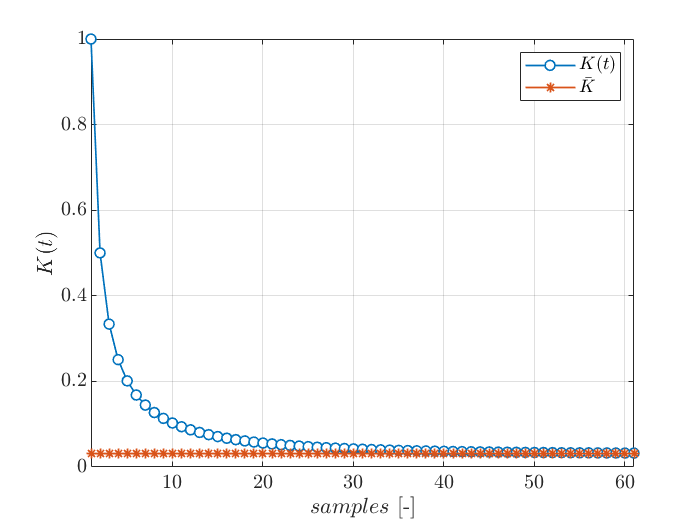

% Check the convergence of the time-varying Kalman gain to the asymptotic value
K_pred = F*K;

figure(3); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(K_pred, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$K(t)$');
plot(K_bar*ones(length(y_meas), 1), '-*', 'Linewidth', 1, 'DisplayName', '$\bar{K}$');
ylabel('$K(t)$', 'Interpreter', 'latex');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
xlim([1 length(y_meas)]); clf;

#### Assess the effect of different parameters

Change the covariance matrix of the process noise

V1_2 = 1e-1; % Increase covariance of the process noise
% Initializations
x_corr2 = zeros(length(y_meas), 1);
x_pred2 = zeros(length(y_meas)+1, 1);
P_corr2 = zeros(length(y_meas), 1);
P_pred2 = zeros(length(y_meas)+1, 1);
x_pred2(1) = x_predInit;
P_pred2(1) = P_predInit;
K2 = zeros(length(y_meas), 1);

% Kalman filtering steps
for t=1:length(y_meas)
   % Correction step
   [K2(t), x_corr2(t), P_corr2(t)] = kf_correction(y_meas(t), H, V2, x_pred2(t), P_pred2(t)); 
   % Prediction step
   [x_pred2(t+1), P_pred2(t+1)] = kf_prediction(u(t), F, G, V1_2, x_corr2(t), P_corr2(t));
end

Compare the estimate obtained with the previous model with this one.

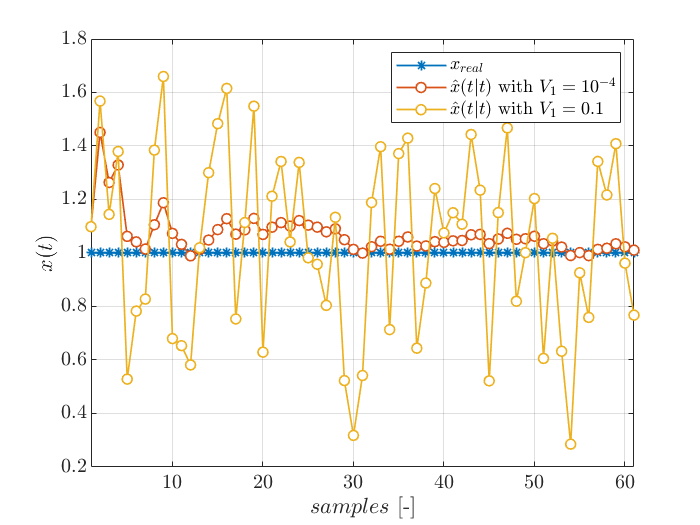

% Superimpose the plots of the true state and the corrected state
figure(4); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(x_true, '-*', 'Linewidth', 1, 'DisplayName', '$x_{real}$');
plot(x_corr, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$ with $V_1=10^{-4}$');
plot(x_corr2, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$ with $V_1=0.1$');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
xlim([1,length(x_true)]);  clf;

**Lowering** the **trust** on the model (that is, in this case, *correct*) leads to a **poorer** **estimate** of the state.

Change the initial trust on the initial estimate of the state

P_predInit2 = 1e-3; % Lower predicted covariance of the state
% Initializations
x_corr3 = zeros(length(y_meas),1);
x_pred3 = zeros(length(y_meas)+1,1);
P_corr3 = zeros(length(y_meas),1);
P_pred3 = zeros(length(y_meas)+1,1);
x_pred3(1) = x_predInit;
P_pred3(1) = P_predInit2;
K3 = zeros(length(y_meas), 1);

% Kalman filtering steps
for t = 1:length(y_meas)
   % Correction step
   [K3(t), x_corr3(t), P_corr3(t)] = kf_correction(y_meas(t), H, V2, x_pred3(t), P_pred3(t)); 
   % Prediction step
   [x_pred3(t+1), P_pred3(t+1)] = kf_prediction(u(t), F, G, V1, x_corr3(t), P_corr3(t));
end

Compare the estimate obtained with the previous model with this one.

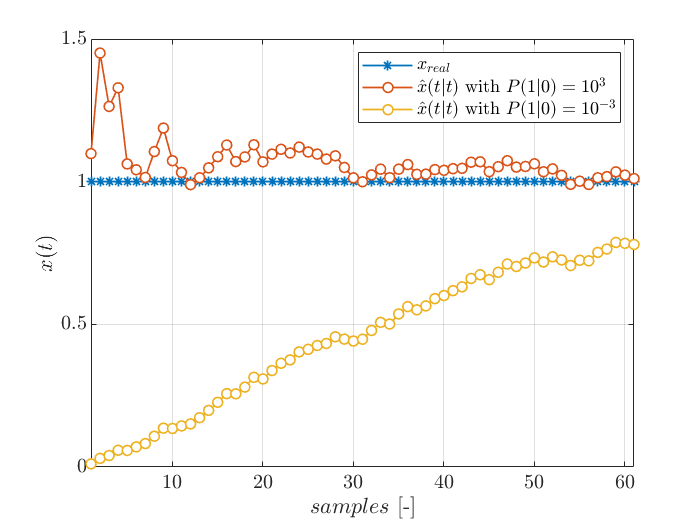

% Superimpose the plots of the true state and the corrected state
figure(5); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(x_true, '-*', 'Linewidth', 1, 'DisplayName', '$x_{real}$');
plot(x_corr, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$ with $P(1|0)=10^{3}$');
plot(x_corr3, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$ with $P(1|0)=10^{-3}$');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
xlim([1, length(x_true)]);  clf;

**Increasing** the level of **trust** on the initial condition **slows down** the **convergence** of the state estimate.

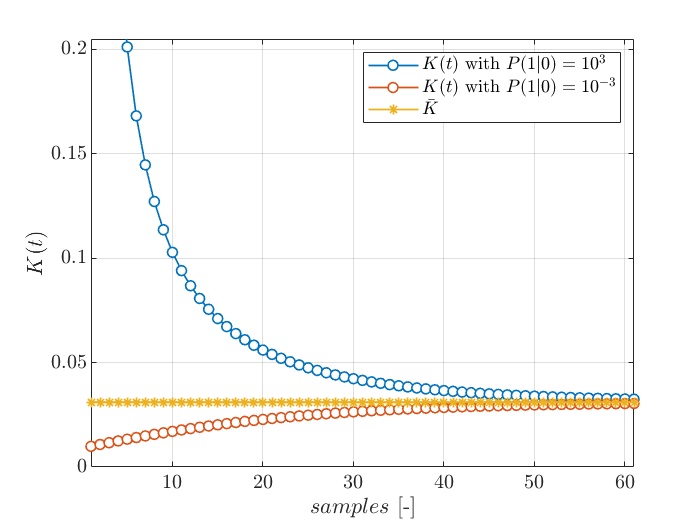

% Check the convergence of the time-varying Kalman gain to the asymptotic value
K3_pred = F*K3;

figure; hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(K_pred, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$K(t)$ with $P(1|0)=10^{3}$');
plot(K3_pred, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$K(t)$ with $P(1|0)=10^{-3}$');
plot(K_bar*ones(length(y_meas), 1), '-*', 'Linewidth', 1, 'DisplayName', '$\bar{K}$');
ylabel('$K(t)$', 'Interpreter', 'latex');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
ylim([0.000 0.205]);
xlim([1 length(y_meas)]); clf;

## Second case: constant filling

Import the data

data_tab = importdata('Filling_tank.xlsx'); % Load data from table
x_true   = data_tab.data(:,1); % Get the true value of the state
y_true   = data_tab.data(:,1); % Get the true value of the state
y_meas   = data_tab.data(:,2); % Get the measurements
u        = zeros(length(y_meas),1); % No input affects the evolution of the level of water

Compare the actual state **(generally not available in practice)** and the measurements

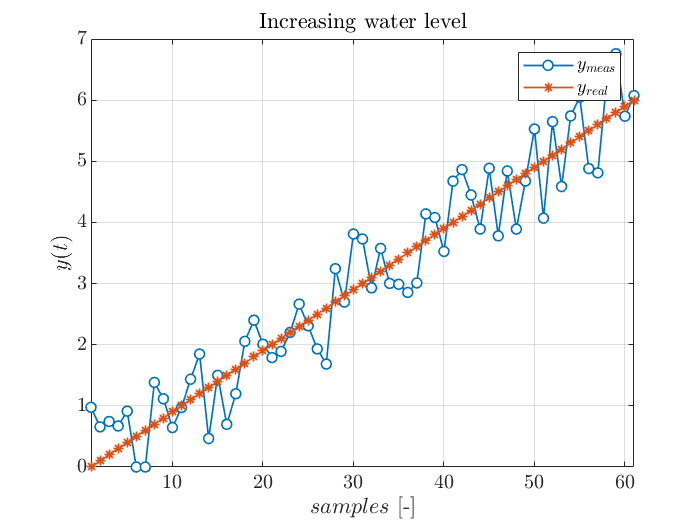

% Superimpose the plots of the true state and the measured output
figure(6); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(y_meas, '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$y_{meas}$');
plot(y_true, '-*', 'Linewidth', 1, 'DisplayName', '$y_{real}$');
legend('Interpreter', 'latex');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$y(t)$', 'Interpreter', 'latex');
title('Increasing water level', 'Interpreter', 'latex');
xlim([1, length(y_true)]); clf;

Use again the **static model**

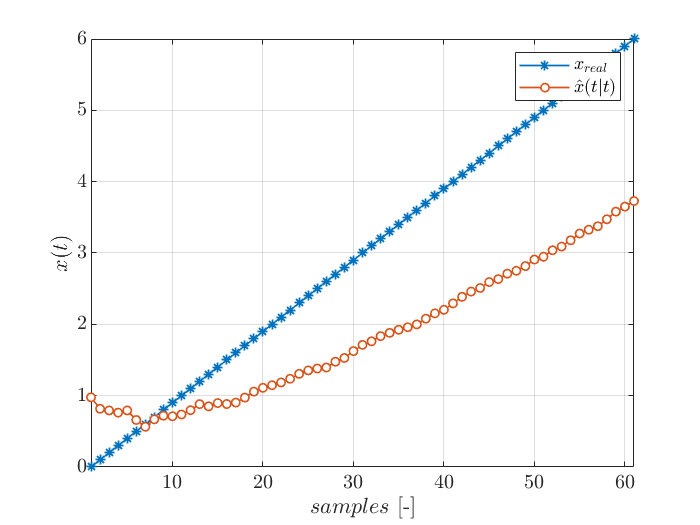

x_corr = zeros(length(y_meas), 1);
x_pred = zeros(length(y_meas)+1, 1);
P_corr = zeros(length(y_meas), 1);
P_pred = zeros(length(y_meas)+1, 1);
x_pred(1) = x_predInit;
P_pred(1) = P_predInit;
K = zeros(length(y_meas), 1);

% Kalman filtering steps
for t = 1:length(y_meas)
   % Correction step
   [K(t), x_corr(t), P_corr(t)] = kf_correction(y_meas(t), H, V2, x_pred(t), P_pred(t)); 
   % Prediction step
   [x_pred(t+1), P_pred(t+1)] = kf_prediction(u(t), F, G, V1, x_corr(t), P_corr(t));
end

figure(7); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(x_true, '-*', 'Linewidth', 1, 'DisplayName', '$x_{real}$');
plot(x_corr, '-o', 'MarkerFaceColor', 'auto', 'MarkerSize', 5,'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
xlim([1, length(x_true)]); clf;

Check the effect of a progressive** increase** of the** process noise covariance**

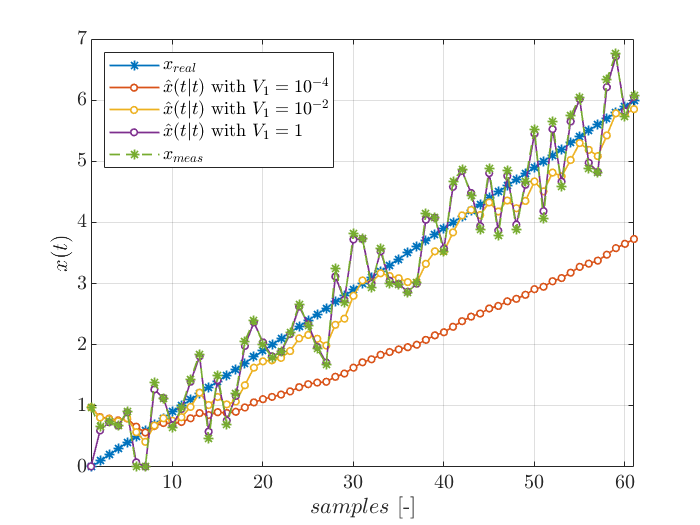

V1_2 = 1e-2;
V1_3 = 1;

x_corr2 = zeros(length(y_meas), 1);
x_pred2 = zeros(length(y_meas)+1, 1);
P_corr2 = zeros(length(y_meas), 1);
P_pred2 = zeros(length(y_meas)+1, 1);
x_pred2(1) = x_predInit;
P_pred2(1) = P_predInit;
K2 = zeros(length(y_meas), 1);

%Kalman filtering steps
for t = 1:length(y_meas)
   % Correction step
   [K2(t), x_corr2(t), P_corr2(t)] = kf_correction(y_meas(t), H, V2, x_pred2(t), P_pred2(t)); 
   % Prediction step
   [x_pred2(t+1), P_pred2(t+1)]=kf_prediction(u(t), F, G, V1_2, x_corr2(t), P_corr2(t));
end

%Kalman filtering steps
for t = 1:length(y_meas)
   % Correction step
   [K3(t), x_corr3(t), P_corr3(t)] = kf_correction(y_meas(t), H, V2, x_pred3(t), P_pred3(t)); 
   % Prediction step
   [x_pred3(t+1), P_pred3(t+1)] = kf_prediction(u(t), F, G, V1_3, x_corr3(t), P_corr3(t));
end

% Superimpose the plots of the true state and the corrected state
figure(8); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(x_true, '-*', 'Linewidth', 1, 'DisplayName', '$x_{real}$');
plot(x_corr, '-o', 'MarkerFaceColor', 'auto', 'MarkerSize', 4, 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$ with $V_1=10^{-4}$');
plot(x_corr2, '-o', 'MarkerFaceColor', 'auto', 'MarkerSize', 4, 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$ with $V_1=10^{-2}$');
plot(x_corr3, '-o', 'MarkerFaceColor', 'auto', 'MarkerSize', 4, 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$ with $V_1=1$');
plot(y_meas,'--*', 'Linewidth', 1, 'DisplayName', '$x_{meas}$');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$x(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex', 'Location', 'northwest');
xlim([1,length(x_true)]);  clf;

The more the process noise covariance is increased, the more the estimate resambles the measurement (I am progressively attributing more trust to the measurements).

In general we can state that:

- if $\frac{V_1 }{V_2 }\gg 1$ we are trusting the measurement over the state (the correction over the prediction), hence the filter will be faster (but noisier)

- if $\frac{V_1 }{V_2 }\ll 1$we are trusting the state over the measurement (the prediction over the correction), hence the filter will be slower

### Linear model

Define the model $L\left(t+1\right)=L\left(t\right)+f$


$$\begin{array}{l}
x_1 \left(t+1\right)=x_1 \left(t\right)+{T_{s\;} x_2 \left(t\right)+w}_1 \left(t\right)\\
x_2 \left(t+1\right)=x_2 \left(t\right)+w_2 \left(t\right)\\
y\left(t\right)=x_1 \left(t\right)+v\left(t\right)
\end{array}$$


Ts = 1; % Sampling time
F = [1 Ts; 0 1]; % The value of the state at t+1 is equal to that of the state at t
G = zeros(2,1); % No exogenous input affects the level of water
H = [1 0]; % The state is fully measured
V1 = [1e-4/3 1e-4/2; 1e-4/2 1e-4]; % We trust the model (obtained dicretizing [0 0; 0 1e-4])  
V2 = 0.1; % We have less trust on the measurements

Note that, V2 **does not correspond** to the **true variance** of the measurement noise (equal to 2). Indeed, we assume we do not know it exactly.

Initialization of all corrected and predicted states, along with the Kalman Gain

x_corr_l = zeros(2, length(y_meas));
x_pred_l = zeros(2, length(y_meas)+1);
P_corr_l = zeros(2, 2, length(y_meas));
P_pred_l = zeros(2, 2, length(y_meas)+1);
x_pred_l(:,1) = x_predInit*[1; 1];
P_pred_l(:,:,1) = P_predInit*eye(2);
K_l = zeros(2, length(y_meas));

#### Kalman filtering steps

for t = 1:length(y_meas)
   % Correction step
   [K_l(:,t), x_corr_l(:,t), P_corr_l(:,:,t)] = kf_correction(y_meas(t), H, V2, squeeze(x_pred_l(:,t)), squeeze(P_pred_l(:,:,t))); 
   % Prediction step
   [x_pred_l(:,t+1), P_pred_l(:,:,t+1)] = kf_prediction(u(t), F, G, V1, squeeze(x_corr_l(:,t)), squeeze(P_corr_l(:,:,t)));
end

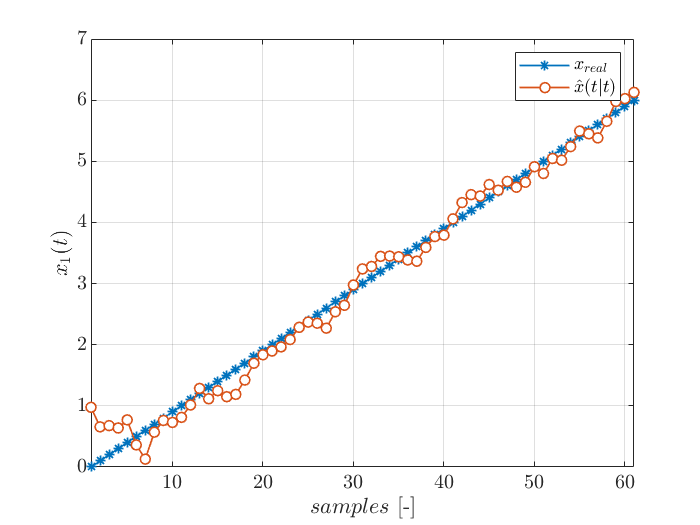

% Superimpose the plots of the true state and the corrected state
figure(9); hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(x_true, '-*', 'Linewidth', 1, 'DisplayName', '$x_{real}$');
plot(x_corr_l(1,:), '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$\hat{x}(t|t)$');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
ylabel('$x_1(t)$', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
xlim([1, length(x_true)]); clf;

Obtain the asymptotic Kalman filter and check the convergence to it.

tank_model = ss(F, [G diag([1 1])], H, [0 0 0], -1); % Define the tank model
[kalmf, K_bar, P_bar] = kalman(tank_model, V1, V2, 0); % Find the Kalman filter and compute its gain and the associated state covariance

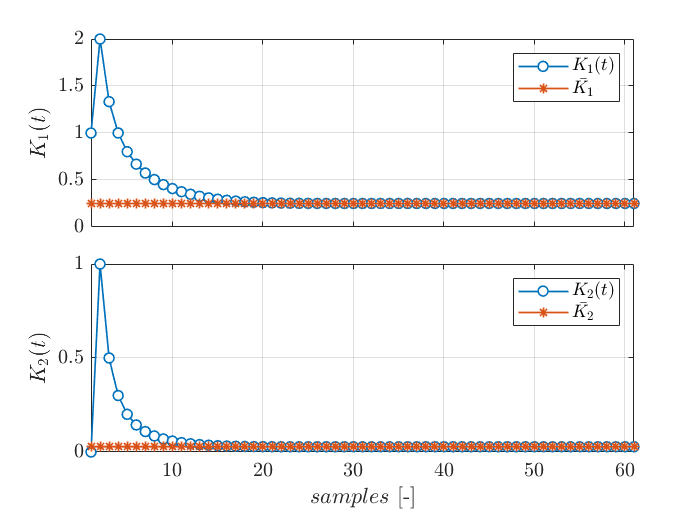

% Check the convergence of the time-varying Kalman gain to the asymptotic
% value
K_pred_l = F*K_l;

% First component
figure(10);
tiledlayout(2, 1, 'TileSpacing', 'compact');
nexttile; hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(K_pred_l(1,:), '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$K_1(t)$');
plot(K_bar(1)*ones(length(y_meas),1), '-*', 'Linewidth', 1, 'DisplayName', '$\bar{K_1}$');
ylabel('$K_1(t)$', 'Interpreter', 'latex');
xticklabels('');
legend('Interpreter', 'latex');
xlim([1 length(y_meas)]);

% Second component
nexttile; hold on; grid on; box on;
set(gca, 'FontSize', 12);
plot(K_pred_l(2,:), '-o', 'MarkerFaceColor', 'auto', 'Linewidth', 1, 'DisplayName', '$K_2(t)$');
plot(K_bar(2)*ones(length(y_meas),1), '-*', 'Linewidth', 1, 'DisplayName', '$\bar{K_2}$');
ylabel('$K_2(t)$', 'Interpreter', 'latex');
xlabel('$samples$ [-]', 'Interpreter', 'latex');
legend('Interpreter', 'latex');
xlim([1 length(y_meas)]); clf;

## Utils

Define the functions embedding the main steps of the Kalman filtering

It can be proven that if $V_{\;12} =0$, Kalman's Filter and Predictor can be splitted as follows:

- Prediction step:      $\begin{array}{l}
\hat{x} \left(t+1|\;t\right)=F\;\hat{x} \left(t|\;t\right)+G\;u\left(t\right)\\
P\left(t+1\right)=F\;P\left(t|\;t\right)F^{T\;} +Q\left(t\right)
\end{array}$

- Correction step:      $\begin{array}{l}
K\left(t\right)=P\left(t|\;t-1\right)H^T {\left(\textrm{HP}\left(t|\;t-1\right)H^T +V_2 \right)}^{-1\;} \\
P\left(t|\;t\right)=\left(I-K\left(t\right)H\right)\;P\left(t|\;t-1\right)\\
\hat{x} \left(t|\;t\right)=\hat{x} \left(t|\;t-1\right)+K\left(t\right)\;\left(y\left(t\right)-H\hat{x} \left(t|\;t-1\right)\right)
\end{array}$

function [x_pred, P_pred] = kf_prediction(u, F, G, V1, x_corr, P_corr)
% Prediction step of the Kalman filter. Given the corrected state x_corr and
% its variance, both are predicted based on the system's model.
% Inputs:
%   - u: current input [mx1]
%   - F: state transition matrix [nxn]
%   - G: input-to-state matrix [nxm]
%   - V1: covariance of the process noise [nxn]
%   - x_corr: corrected state at the previous time step [nx1]
%   - P_corr: corrected covaraince of the state at the pevious time step [nxn]
% Outputs:
%   - x_pred: predicted state estimate
%   - P_pred: predicted variance of the state
    
    x_pred = F*x_corr + G*u;
    P_pred = F*P_corr*F' + V1;
end

function [K, x_corr, P_corr] = kf_correction(y_meas, H, V2, x_pred, P_pred)
% Correction step of the Kalman filter. Given the predicted state x_pred and
% its variance, both are corrected based on the measurements.
% Inputs:
%   - y_meas: current measured output [px1]
%   - H: state-to-output matrix [pxn]
%   - V2: covariance of the measurement noise [pxp]
%   - x_pred: predicted state at the previous time step [nx1]
%   - P_pred: predicted covaraince of the state at the pevious time step [nxn]
% Outputs:
%   - K: updated Kalman filter gain
%   - x_corr: corrected state estimate
%   - P_corr: corrected covariance of the state

    n = length(x_pred); % Obtain the dimension of the state
    K = (P_pred*H')/(H*P_pred*H' + V2); % Update the Kalman filter gain
    P_corr = (eye(n) - K*H)*P_pred; % Correct the state variance based on the new Kalman gain.
    x_corr = x_pred + K*(y_meas - H*x_pred); % Correct the state estimate based on the current measurement
end
